# Equivalence Testing

Created Sep 11, 2021

clear; clc;
cd('/Users/duncan/OneDrive - University of Delaware - o365/Documents/Presentations/EquivalenceTesting')

## Lakens

Replicate Independent Samples (equivalence bounds based on raw scores) from Excel sheet 

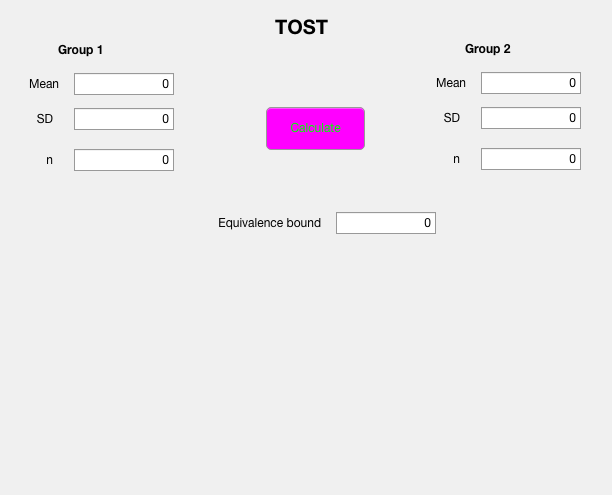

TOST_indep_raw(); 


% tstat = @(mu1, mu2, delta, var1, var2, n1, n2) (mu1 - mu2 - delta) / sqrt((var1/n1) + (var2/n2)); 
% dfw = @(var1, n1, var2, n2) ((var1/n1) + (var2/n2))^2 / (((var1/n1)^2/(n1-1)) + ((var2/n2)^2/(n2 - 1)));
% tdist2T = @(t,v) (1-betainc(v/(v+t^2),v/2,0.5));    % 2-tailed t-distribution
% tdist1T = @(t,df) (1-tdist2T(t,df))/2;              % 1-tailed t-distribution
% ES = @(mu1, mu2, pooledstd) (mu1 - mu2) / pooledstd; 
% cohenD = @(delta, n1, var1, n2, var2) delta / (sqrt((((n1 - 1)*var1 + (n2 - 1)*var2)) / (n1 + n2 - 2)));  
% 
% TU = tstat(5.25, 5.22, 0.3836, 0.95^2, 0.83^2, 95, 89);
% TL = tstat(5.25, 5.22, -0.3836, 0.95^2, 0.83^2, 95, 89);
% DF = dfw(0.95^2, 95, 0.83^2, 89);
% pL = tdist1T(TL, DF);
% pU = tdist1T(TU, DF);
% effectsize = ES(5.25, 5.22, (0.95^2 + 0.83^2)/2);
% cohenDL = cohenD(-0.3836, 95, 0.95^2, 89, 0.83^2); 
% cohenDU = cohenD(0.3836, 95, 0.95^2, 89, 0.83^2); 
% 
% fprintf('T-statistic upper = %.4f', TU)
% fprintf('T-statistic lower = %.4f', TL)
% fprintf('Degrees of freedom = %.4f', DF)
% fprintf('p-value for lower = %.4f', pL)
% fprintf('p-value for upper = %.4f', pU)
% fprintf('Effect size = %.4f', effectsize)
% fprintf('Cohen''s D lower = %.4f', cohenDL)
% fprintf('Cohen''s D upper = %.4f', cohenDU)

## Limentani et al.